# Exercise 5: Draw Prepared Images Step by Step by Badweh 

Given simpe image, we explore the step by step of transformPixelsToMeters() function. Transforming pixel to meter. 

Step 1.  Given the image line trace pixel and it's pixel, segmentsPix xLimPix yLimPix,  and the drawable region of the whiteboard, xLim yLim Calcuate the size, or xRange and y Range

Step 2. Calculate the scale factor

Step 3. Observe the line trace location w.r.t. pixel's orgin (0,0)

Step 3b. Shift line trace to pixel's orgin

Step 3c. Scale line trace pixel to meter

Step 3d. Move the scaled pixel to Whiteboard's drawable region

## Display Image. Load line trace data and White board data. 

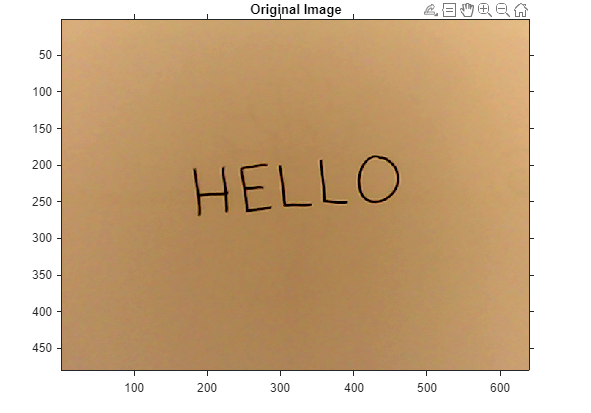

imshow('HELLO.png')
axis on
title('Original Image')

% load H.mat segmentsPix 
load U3.mat segmentsPix xLimPix yLimPix
load WhiteboardLimits.mat xLim yLim
fraction = 0.7;

## Plot pixels chosen from sample image

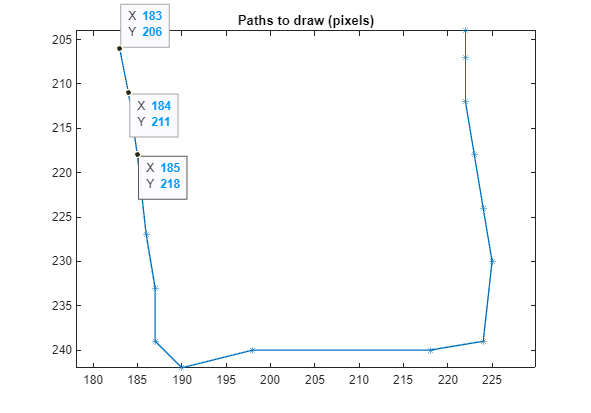

for ii = 1:1
    coords = segmentsPix{1};
    plot(coords(:,2),coords(:,1),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (pixels)')

% segmentsMeters = transformPixelsToMeters(segmentsPix,xLim,yLim,xLimPix,yLimPix,fraction); 

## Explore transformPixelMeter() - Badweh

% Define board size: max and min

% inputs
xLim

xLim =     0.0600    0.9400


yLim

yLim =     0.1300    0.4100


xLimPix

xLimPix =    183   225


yLimPix

yLimPix =    204   242


fraction

fraction = 0.7000



%the ranges xRange, yRange, xRangePix, and yRangePix.
%% Board x and y's min and range
xMinM = xLim(1)

xMinM = 0.0600

yMinM = yLim(1)

yMinM = 0.1300

xRangeM = diff(xLim)

xRangeM = 0.8800

yRangeM = diff(yLim)

yRangeM = 0.2800


% Determine the range of the coordinates to draw
%% image size, x and y's min and range
xMinPix = xLimPix(1)

xMinPix = 183

yMinPix = yLimPix(1)

yMinPix = 204

xRangePix = diff(xLimPix)

xRangePix = 42

yRangePix = diff(yLimPix)

yRangePix = 38



% Scale from pixels to real world units (meters)
xScaleFactor = fraction * xRangeM/xRangePix

xScaleFactor = 0.0147

yScaleFactor = fraction * yRangeM/xRangePix

yScaleFactor = 0.0047

% Pick the smaller scale factor. If both are NaN, pick 0.
pix2M = min(xScaleFactor,yScaleFactor)

pix2M = 0.0047

if isnan(pix2M)
    pix2M = 0;
end

% Identify the origin of the scaled drawing
centerMeters = [xMinM yMinM] + [xRangeM yRangeM]/2 %% Whtieboard

centerMeters =     0.5000    0.2700


drawingOriginM = centerMeters - pix2M*[xRangePix yRangePix]/2 %% Whiteboard

drawingOriginM =     0.4020    0.1813


## Pixel Image

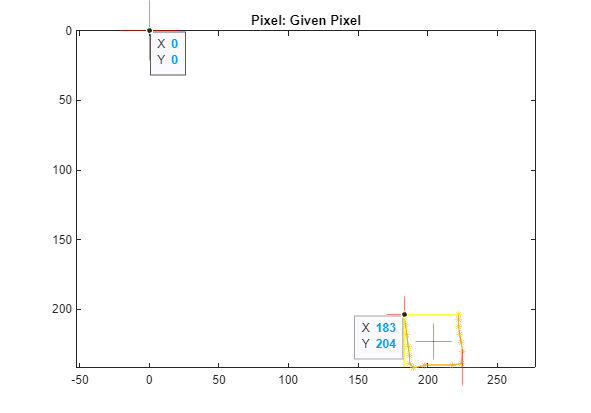

%% Line trace location w.r.t. pixel's orgin
for ii = 1:1
    coords = segmentsPix{1};
    plot(coords(:,2),coords(:,1),'-*')
    hold on
end
plot(0,0, '+r', 'MarkerSize',50) %% pixel orgin (0,0)

plot(xMinPix,yMinPix,'+r','MarkerSize',30) %% image trace pixel x, y min
plot(xLimPix(2),yLimPix(2),'+r','MarkerSize',30) %% pixel x, y max
plot(xMinPix+xRangePix/2, yMinPix+yRangePix/2, '+r','MarkerSize',30) %% Center of pixel trace
plot([xLimPix(1) xLimPix(1)],[yLimPix(1) yLimPix(2)], 'y') % yRnagePix
plot([xLimPix(1) xLimPix(2)],[yLimPix(1) yLimPix(1)], 'y') % xRangePix

hold off
axis equal ij
title('Pixel: Given Pixel')

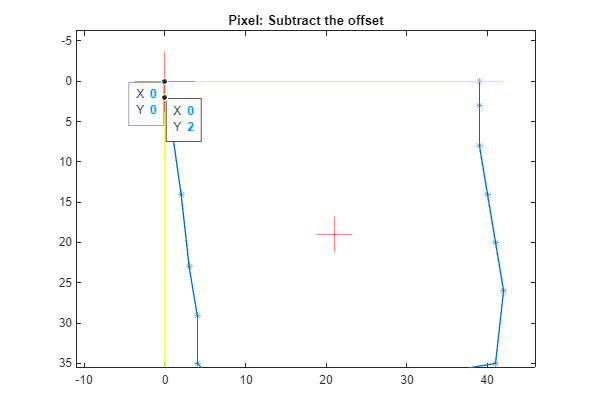



%% move the line trace to pixel's orgin by subtract the offset to shift to pixel origin
originPix = fliplr(coords)-[xMinPix yMinPix];
plot(originPix(:,1),originPix(:,2),'-*')
hold on
plot(xRangePix/2, yRangePix/2, '+r','MarkerSize',30) %% Center of pixel trace
plot([0 0],[0 yRangePix], 'y') % yRnage
plot([0 xRangePix],[0 0], 'y') % xRange
plot(0,0, '+r', 'MarkerSize',50)
axis equal ij
title('Pixel: Subtract the offset')
hold off

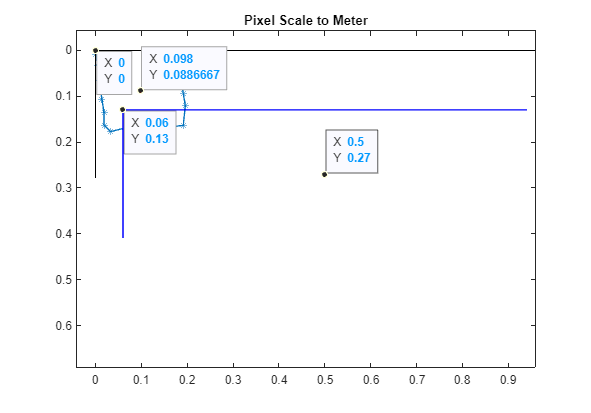




%% FROM PIXEL TO METER
% transform pixel to meter by Scale factor pix2M 
scale = pix2M*originPix;
sacleCenter = pix2M*[xRangePix yRangePix]/2; %% scale Center of pixel trace
plot(scale(:,1),scale(:,2),'-*')
hold on
plot(sacleCenter(1), sacleCenter(2), '+r') % plot scaled Center trace
plot(centerMeters(1), centerMeters(2), '+k') % center of whiteboard drawable region
% Whiteboard
plot([0 0],[0 yRangeM], 'k') % whiteboard y
plot([0 1],[0 0], 'k') % whiteboard x
% Drawable Region
plot([xMinM xMinM],[yMinM yMinM+yRangeM], 'b') % drawable region yRnage
plot([xMinM xMinM+xRangeM],[yMinM yMinM], 'b') % drawable region xRange
axis equal ij
title('Pixel Scale to Meter')
hold off

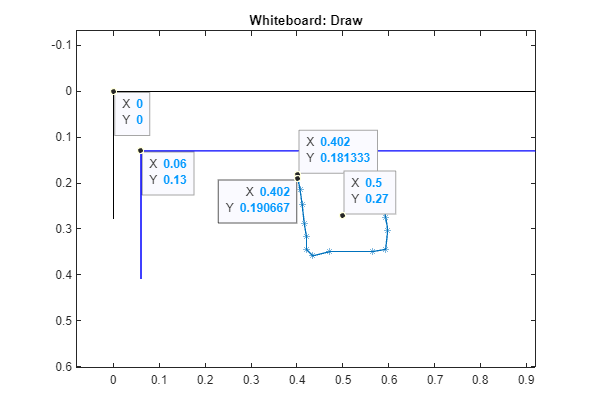



% Shift to Drawable Region
meter = scale + drawingOriginM;
scaledMeter = centerMeters - sacleCenter;
plot(meter(:,1),meter(:,2),'-*')
hold on
plot(scaledMeter(1), scaledMeter(2), '+r') % plot scaled Center trace -- Drawing Orgin
plot(centerMeters(1), centerMeters(2), '+k') % center of whiteboard drawable region
% Whiteboard
plot([0 0],[0 yRangeM], 'k') % whiteboard y
plot([0 1],[0 0], 'k') % whiteboard x
% Drawable Region
plot([xMinM xMinM],[yMinM yMinM+yRangeM], 'b') % drawable region yRnage
plot([xMinM xMinM+xRangeM],[yMinM yMinM], 'b') % drawable region xRange
axis equal ij
title('Whiteboard: Draw')
hold off


segmentsMeters = meter

segmentsMeters =     0.4020    0.1907
    0.4067    0.2140
    0.4113    0.2467
    0.4160    0.2887
    0.4207    0.3167
    0.4207    0.3447
    0.4347    0.3587
    0.4720    0.3493
    0.5653    0.3493
    0.5933    0.3447


*Copyright 2018 - 2020 The MathWorks, Inc.*